***2.三维图像绘制***

**(1)三维曲线**

plot3函数:

t=linspace(0,10*pi,100)

t =                          0         0.317332591271696         0.634665182543393         0.951997773815089          1.26933036508679          1.58666295635848          1.90399554763018          2.22132813890187          2.53866073017357          2.85599332144527          3.17332591271696          3.49065850398866          3.80799109526036          4.12532368653205          4.44265627780375          4.75998886907544          5.07732146034714          5.39465405161884          5.71198664289053          6.02931923416223          6.34665182543393          6.66398441670562          6.98131700797732          7.29864959924902          7.61598219052071          7.93331478179241           8.2506473730641           8.5679799643358          8.88531255560749          9.20264514687919          9.51997773815089          9.83731032942258          10.1546429206943           10.471975511966          10.7893081032377          11.1066406945094          11.4239732857811          11.7413058770528        

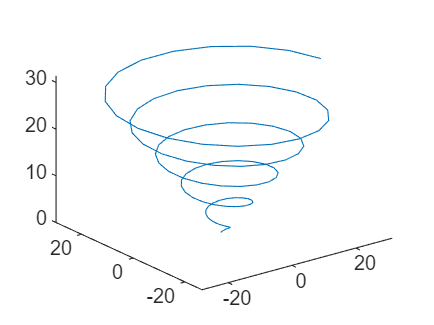

x=sin(t)+t.*cos(t);
y=cos(t)-t.*sin(t);
z=t;
plot3(x,y,z)

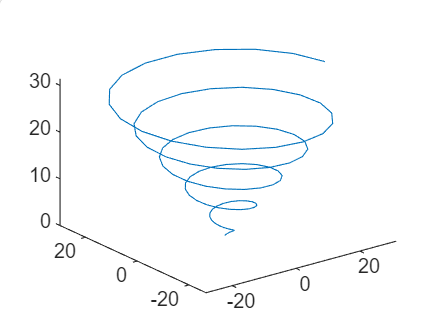

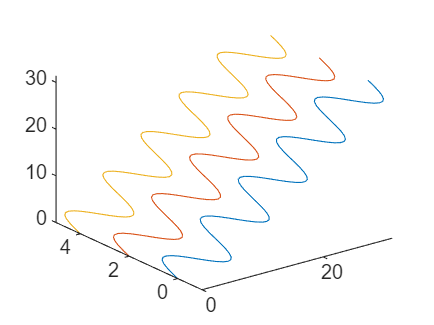

t=t.';
x=[t,t,t];
y=[sin(t),sin(t)+2,sin(t)+4];
z=t;
plot3(x,y,z)

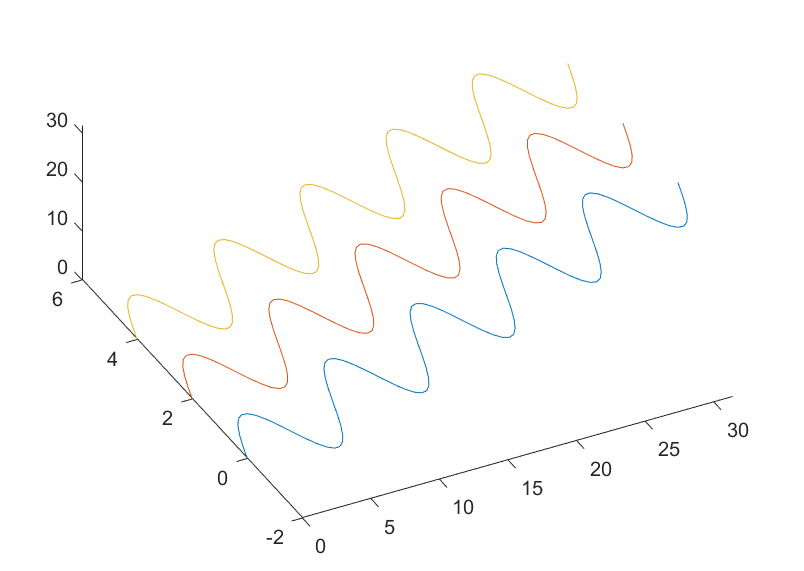

x=t;
y=[sin(t);sin(t)+2;sin(t)+4];
z=t;
%plot3(x,y,z)

多组数据:

plot3(x,sin(t),z,x,sin(t)+2,z,x,sin(t)+4,z);

fplot3函数:

墨西哥帽顶曲线:

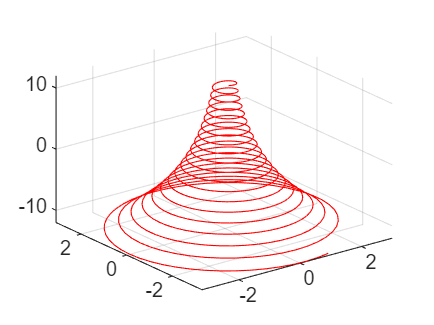

x=@(t) exp(-t/10).*sin(5*t);
y=@(t) exp(-t/10).*cos(5*t);
z=@(t) t;
fplot3(x,y,z,[-12,12],'-r');

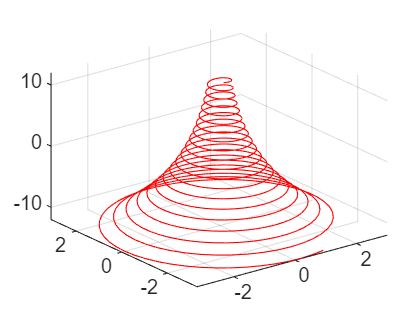

**(2)三维曲面**

平面网格数据的生成:

利用矩阵运算生成+利用meshgrid函数生成

x=[2:6];
y=[3:8]';
X=ones(size(y))*x%size(y):y的大小

X =      2     3     4     5     6
     2     3     4     5     6
     2     3     4     5     6
     2     3     4     5     6
     2     3     4     5     6
     2     3     4     5     6


Y=y*ones(size(x))

Y =      3     3     3     3     3
     4     4     4     4     4
     5     5     5     5     5
     6     6     6     6     6
     7     7     7     7     7
     8     8     8     8     8


%利用meshgrid函数另解
[X,Y]=meshgrid(x,y)

X =      2     3     4     5     6
     2     3     4     5     6
     2     3     4     5     6
     2     3     4     5     6
     2     3     4     5     6
     2     3     4     5     6


Y =      3     3     3     3     3
     4     4     4     4     4
     5     5     5     5     5
     6     6     6     6     6
     7     7     7     7     7
     8     8     8     8     8


X

X =      2     3     4     5     6
     2     3     4     5     6
     2     3     4     5     6
     2     3     4     5     6
     2     3     4     5     6
     2     3     4     5     6


Y

Y =      3     3     3     3     3
     4     4     4     4     4
     5     5     5     5     5
     6     6     6     6     6
     7     7     7     7     7
     8     8     8     8     8


绘制三维曲面的函数:

mesh函数:(网格)

surf函数:(着色)

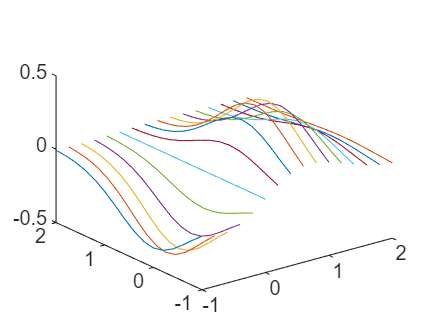

x=-1:0.2:2;
[X,Y]=meshgrid(x);%x,y是一样的地位
Z=X.*exp(-X.^2-Y.^2);
plot3(X,Y,Z)

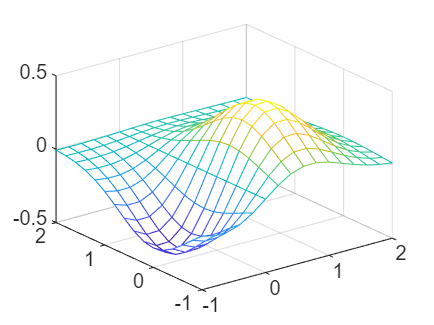

mesh(X,Y,Z)

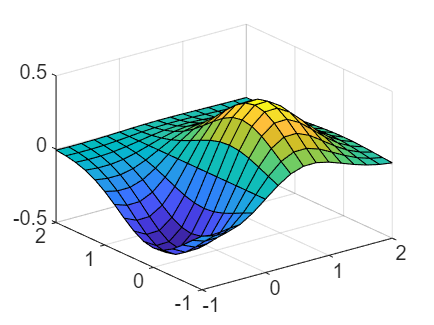

surf(X,Y,Z)

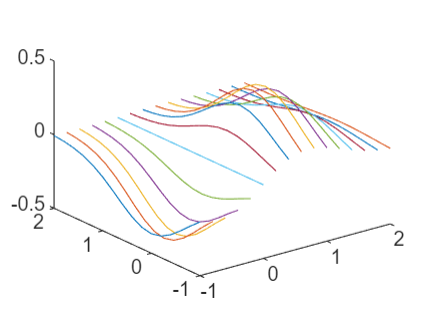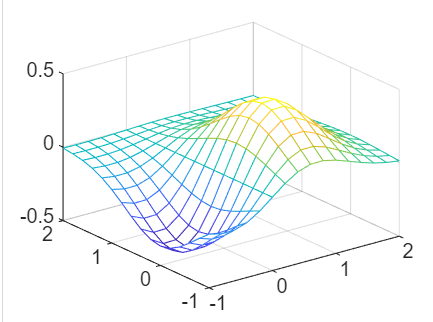

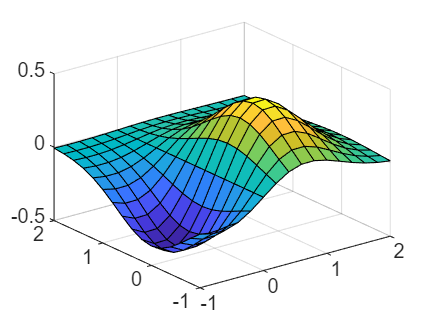

例题:

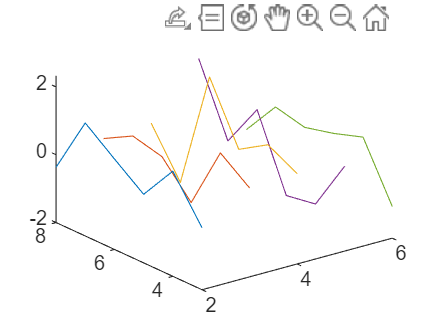

x=[2:6];
y=[3:8];
[X,Y]=meshgrid(x,y);
Z=randn(size(X));
plot3(X,Y,Z)